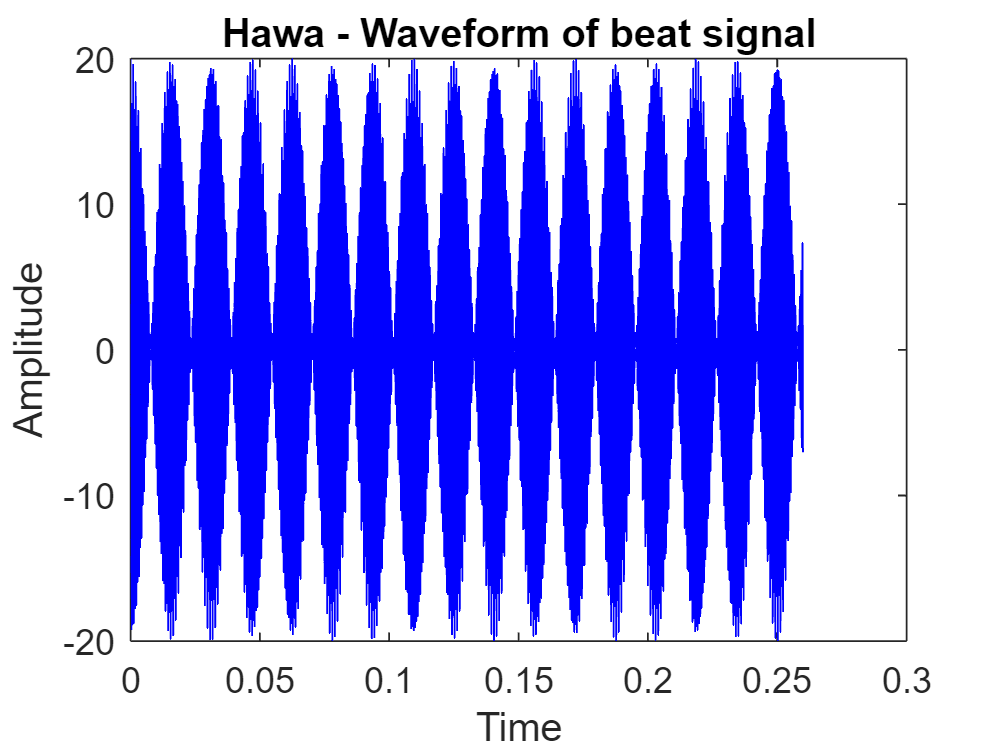

% Beat signal parameters
A = 10;
B = 10;
fc = 2000;
delf = 32;
fsamp = 11025;
dur = 0.26;

% Generating beat signal
[xx, tt] = beat(A, B, fc, delf, fsamp, dur);

% Plot the beat signal
figure;
plot(tt, xx, 'b');
xlabel('Time');
ylabel('Amplitude');
title('Hawa - Waveform of beat signal', 'FontWeight', 'Bold');

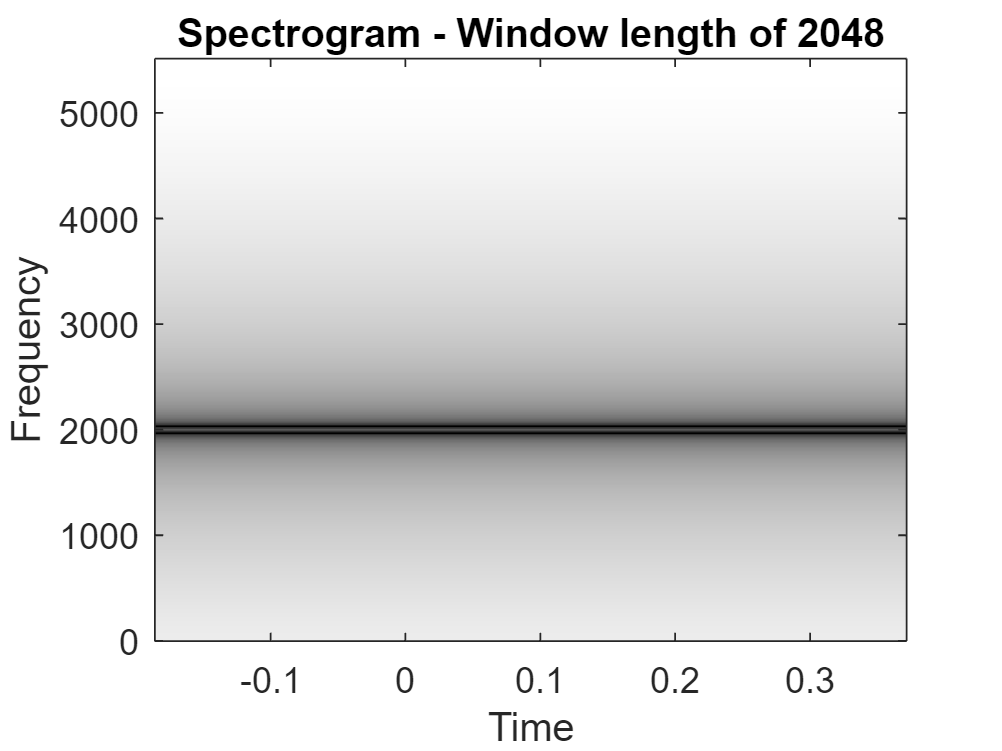


% Spectrogram with window length of 2048
figure;
specgram(xx, 2048, fsamp);
colormap(1-gray(256));
title('Spectrogram - Window length of 2048');

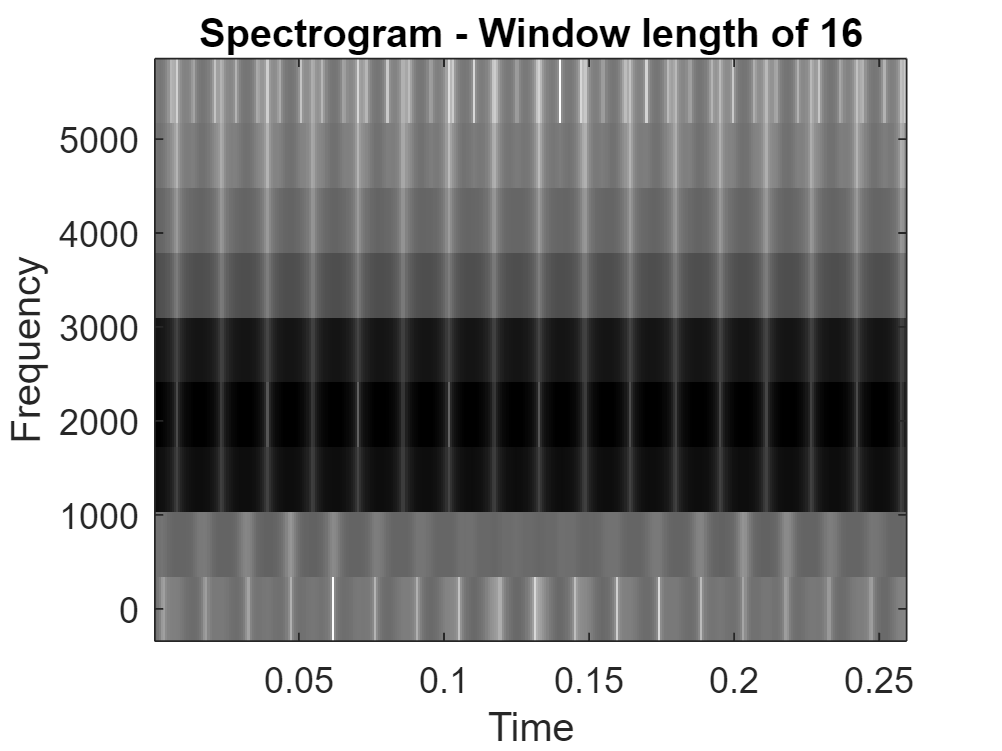


% Spectrogram with window length of 16
figure;
specgram(xx, 16, fsamp);
colormap(1-gray(256));
title('Spectrogram - Window length of 16');